# LAB 3 guidance

# Prelab solution (10'')

2.  Clear that the format of first-oder zero input response is $$y(t) = c\,e^{-at}x(0)$$.

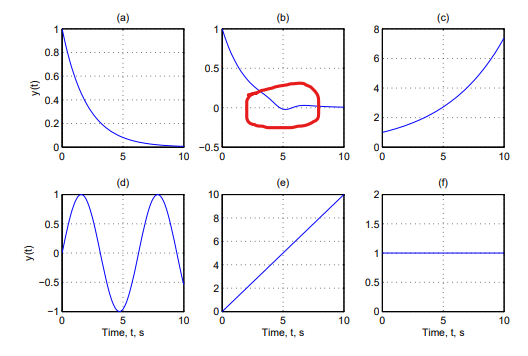

2.(a) Fig.(a), Fig.(c) and Fig.(f) can correspond to a first order linear system.

2.(b) Fig.(b) oscillating near 0 in x-axis. Fig.(d) is a sine wave. Fig.(e) is a slant line. All these features can not matching the form of equation y(t).

2.(c) 

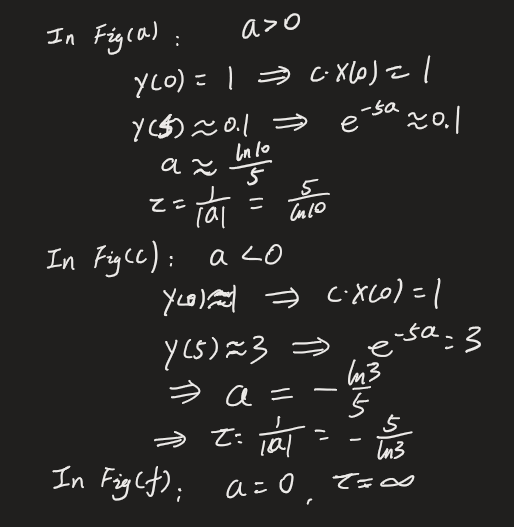

3.

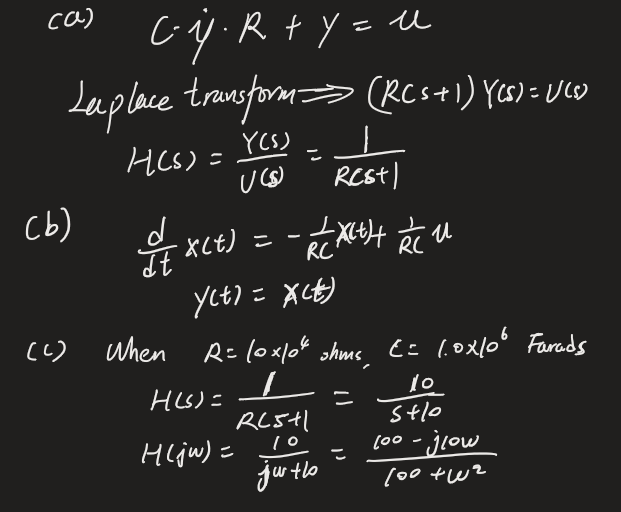

w = [0,0.01,0.1,1,10,100]

w =          0    0.0100    0.1000    1.0000   10.0000  100.0000


clear i;
H = (100 - i*10.*w)./(100 + w.^2);
% Magnitude
abs(H)

ans =     1.0000    1.0000    1.0000    0.9950    0.7071    0.0995


% Phase
rad2deg(angle(H)) % Unit: degree

ans =          0   -0.0573   -0.5729   -5.7106  -45.0000  -84.2894


3.(d)

H = tf(10,[1 10])

H =
 
    10
  ------
  s + 10
 
Continuous-time transfer function.



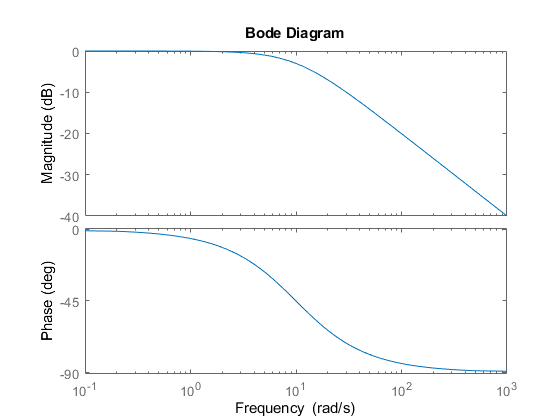

bode(H)

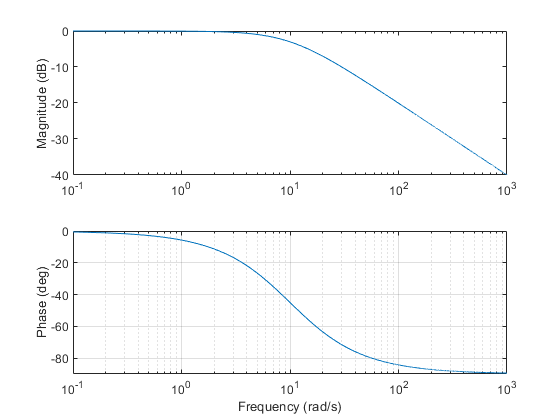

%For proving (c)
w = 0.1:0.1:1000;
H = (100 - i*10.*w)./(100 + w.^2);
% Compute magnitude using eqn.(11)
M = abs(H);
% Compute phase using eqn.(11)
Phi = rad2deg(angle(H));
figure
subplot(211)
% Semilogx to uniformize the x-axis to the results in 'bode'
% log10 to compute the DB of M(s)
semilogx(w,20*log10(M));
ylabel('Magnitude (dB)')
xlim([0.1,1000])
ylim([-40,0])
subplot(212)
semilogx(w,Phi);
ylim([-90,0])
grid on
ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')

# 4.1 Part 1 – Time Constant Estimation (20'')

1. (10'')

% load data
load('EE105_Lab3data.mat');
% Plot y versus t. Make sure that the figure is properly
% labeled as indicated in Lab 1.

2. (5'' for each method, total 10'')

Estimating the time constant have to be done by MATLAB code. No points will be given by manully computation.

Method 1:

y($\tau$) = 0.37y(0)

% Find the value for y_tau. Note that the index of a vector in MATLAB start
% at 1.
% You get the y(tau), but how to find tau?
% Search 'find' in MATLAB documentation, read the statemetent.
% For example,
h = [4 3 -11 14 0 -6 8];
x = -11;
% If I want to find where is 11 in array h, I can use
ind = find(h == x)

ind = 3

% What if x = -11.1, find the closest position in 'h'?
% Directly use find(h == x) will cause empty output.
% You can find the minimum of abs(h - x). (Try MATLAB function 'min')

% Once you get the index 'ind' in vector y.
% Then tau = t_out(ind);

Method 2:

Compute a. a = - dydt(0)/y(0).

Use y(t(1)) and y(t(2)) to compute the slope dydt(0) at t = 0.

Then compute $\tau$.

# 4.2 Part 2 – Simulation (70'')

**You report should show the simulink model, the output and input by taking screenshot and inserting to your report.**

**For the output and input figure, you should state which curve is the input and which curve is the output.**

**Submit three simulink files to MATLAB Drive.**

1.  (Name the simulink file as 'part2_1')

Note that: The ‘Max. step size’ is 0.01*tau and the duration of the simulation is 10*tau.


$$H=\frac{1}{\mathrm{RCs}+1}=\frac{\frac{1}{\mathrm{RC}}}{s+\frac{1}{\mathrm{RC}}},\mathrm{hence},a=10,b=10,c=1\ldotp$$


The model (**The figure below is just an example**): (5'')

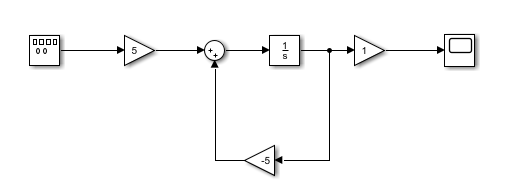

Output and input (for initial condition of the integrator to 1.0): (3'')  

Output and input (for initial condition of the integrator to 0.0): (2'')  

2.  (Name the simulink file as 'part2_2')

The model: (5'')

Output and input: (10'') 

2.(c) How long does the response take to get to steady state?  (5'')

 Show the '**cursor measurement**' and answering this question.

 How does this compare with the time constant?   (5'')

2.(d)  (5'')

3. (Name the simulink file as 'part2_3') 

In your report, you just need to show the simulation result for $\omega =1\ldotp 00\ldotp$

The model: (5'')

Output and input: (10'')

3.(e) Does the magnitude of your output = 0.995? (5'') 

Measure the phase between y and u in the simulation results. Show the '**cursor measurement**'. Measure the phase shift. Note that the axis in the 'scope' is time 't'. You shoud convert the '$\Delta T$' to degree. Does the phase shift you measured approximatelly equal to -5.7106 degree? (10'')